# Plotting System Responses

This example shows how to plot the time and frequency responses of SISO and MIMO linear systems.

## Time Responses

Create a linear system. For this example, create a third-order transfer function.

sys = tf([8 18 32],[1 6 14 24])


sys =
 
     8 s^2 + 18 s + 32
  -----------------------
  s^3 + 6 s^2 + 14 s + 24
 
Continuous-time transfer function.


You can plot the step and impulse responses of this system using the `step` and `impulse` commands.

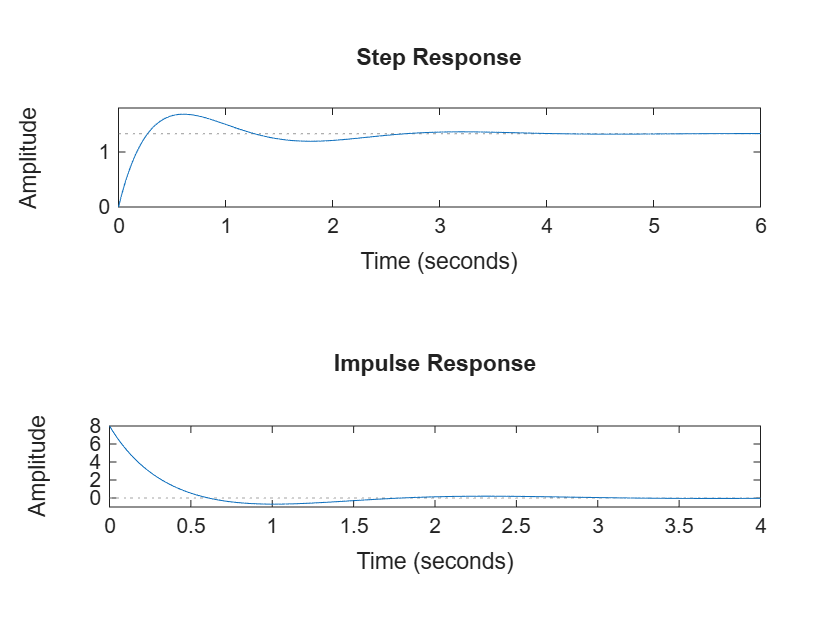

subplot(2,1,1)
step(sys)
subplot(2,1,2)
impulse(sys)

You can also simulate the response to an arbitrary signal, such as a sine wave, using the `lsim` command. The input signal appears in gray and the system response in blue.

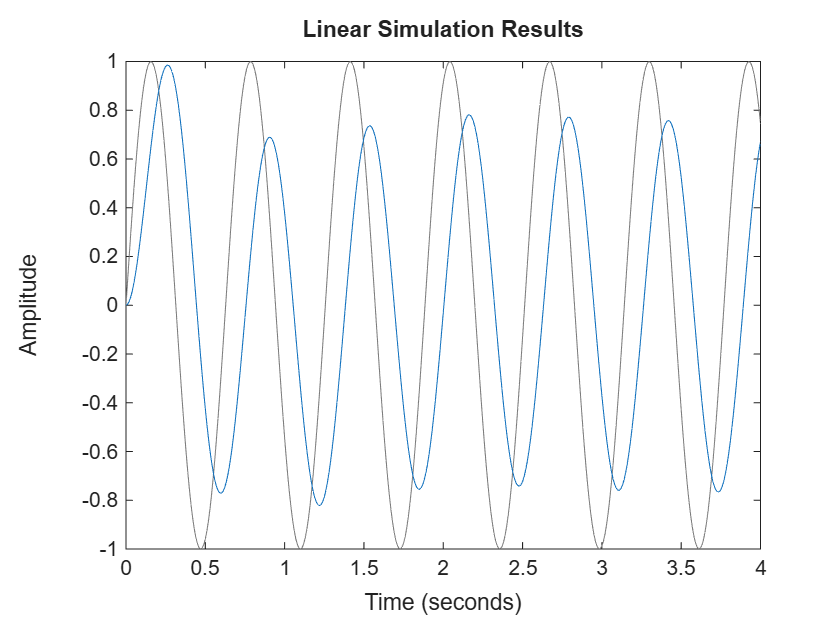

figure
t = 0:0.01:4;
u = sin(10*t);
lsim(sys,u,t)   % u,t define the input signal

You can use the plotting commands with continuous or discrete `tf`, `ss`, or `zpk` models. For state-space models, you can also plot the unforced response from some given initial state. For example:

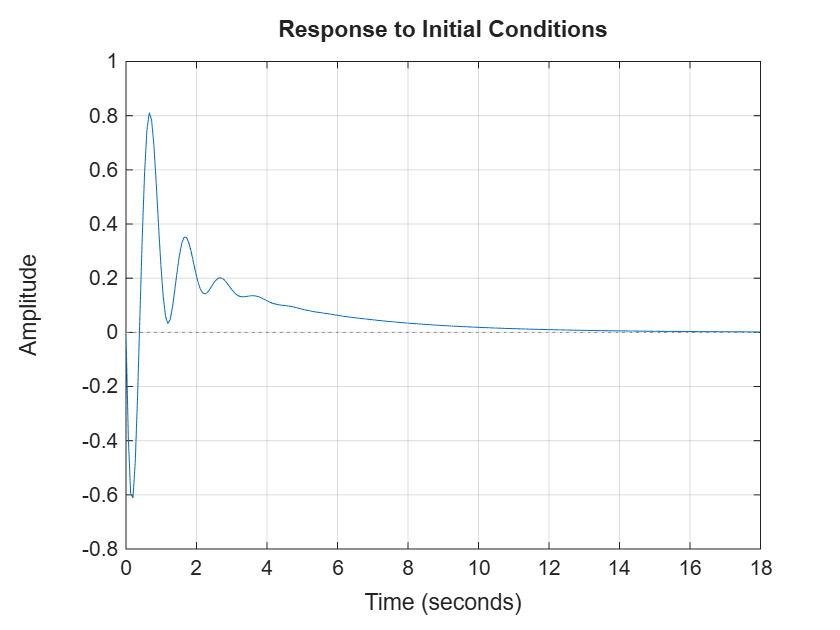

A = [-0.8 3.6 -2.1;-3 -1.2 4.8;3 -4.3 -1.1];
B = [0; -1.1; -0.2];
C = [1.2 0 0.6];
D = -0.6;
G = ss(A,B,C,D);
x0 = [-1;0;2];  % initial state
initial(G,x0)
grid

## Frequency Responses

Frequency-domain analysis is key to understanding stability and performance properties of control systems. Bode plots, Nyquist plots, and Nichols charts are three standard ways to plot and analyze the frequency response of a linear system. You can create these plots using the `bode`, `nichols`, and `nyquist` commands.

Create a linear system.

sys = tf([8 18 32],[1 6 14 24])


sys =
 
     8 s^2 + 18 s + 32
  -----------------------
  s^3 + 6 s^2 + 14 s + 24
 
Continuous-time transfer function.


Create a Bode plot for this system.

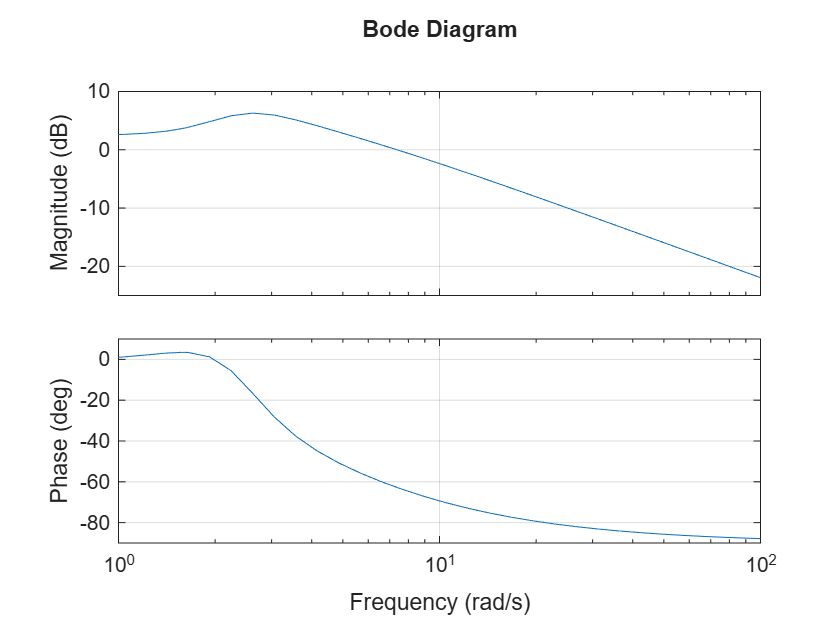

bode(sys)
grid

Create a Nyquist plot for this system.

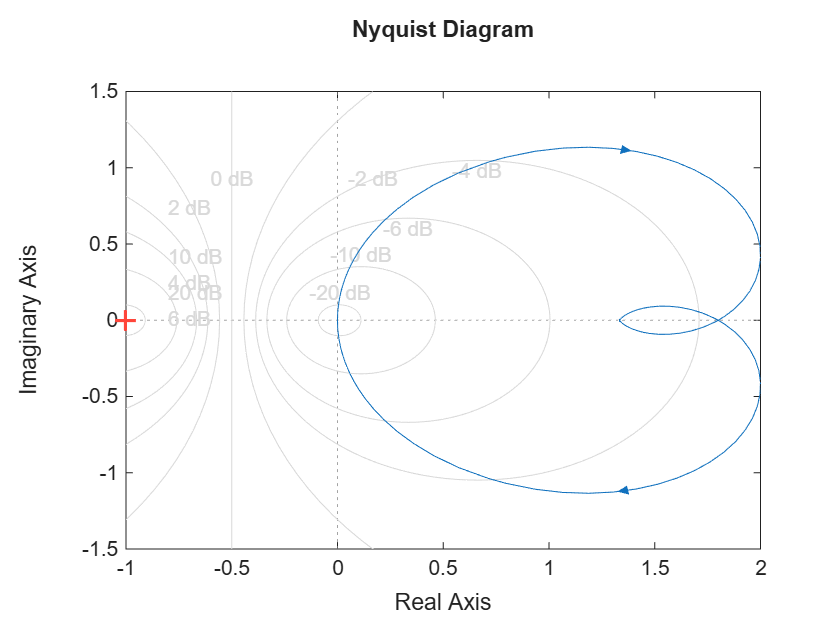

nyquist(sys)
grid

Create a Nichols chart for this system.

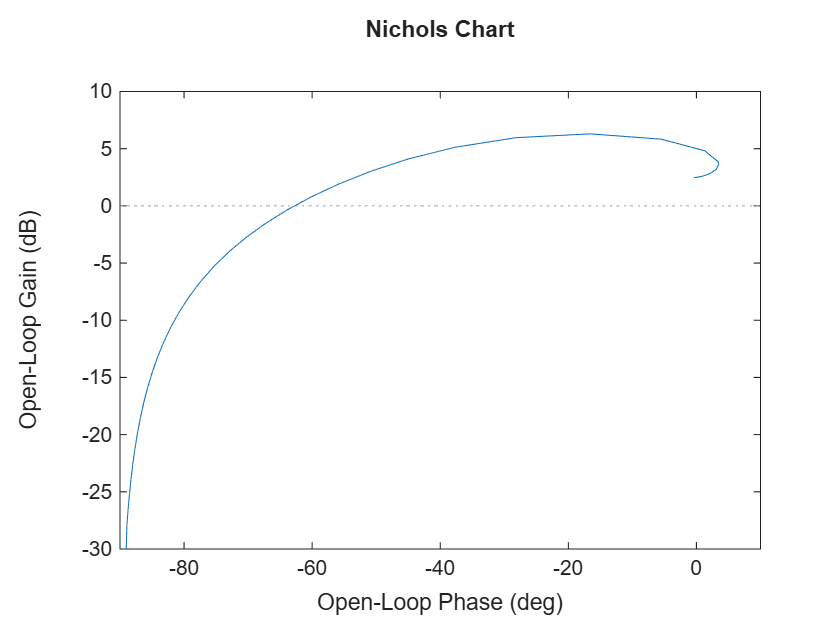

nichols(sys)
grid

*Copyright 2025 The MathWorks, Inc.*